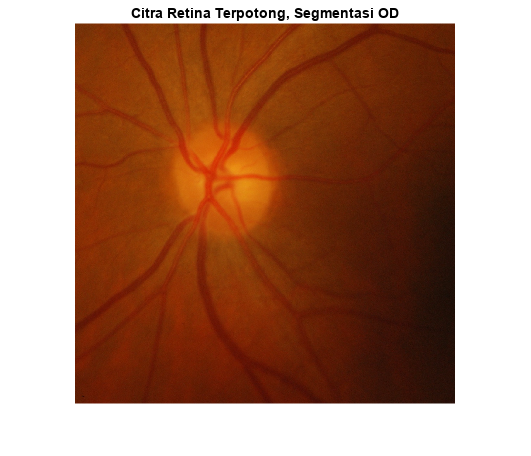

%Open file
[image, pathname] = uigetfile('*.png');
J = imread(image);

%Crop gambar untuk menghilangkan border hitam pada gambar asli
I = imcrop(J,[350 350 1250 1250]);
HSV = rgb2hsv(I);

%%Cek RGB
R = I(:,:,1)*1.2;
G = I(:,:,2)*1.2;
B = I(:,:,3)*1.2;

%figure, imshow(R)
%figure, imshow(G)
%figure, imshow(B)

%%Cek HSV
H = HSV(:,:,1);
S = HSV(:,:,2);
V = HSV(:,:,3);

figure, imshow(I)
title('Citra Retina Terpotong, Segmentasi OD')

%figure, imshow(H)
%figure, imshow(S)
%figure, imshow(V)

%Disimpulkan untuk lokalisasi dan segmentasi menggunakan nilai Value citra
%Ambil value citra
%Invert warna
%figure, imshow(imcomplement(adapthisteq(V)))
%Mengubah kontras citra gray
Vnew = imadjust(V) - imcomplement(V);
%figure, imshow(Vnew)
level = graythresh(V);
%Vnew = imadjust(Vnew);
ne = Vnew > level;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 6)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


dil = imdilate(fill,se)

dil = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

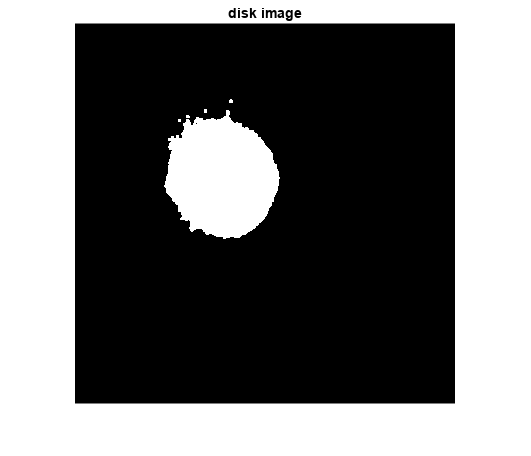

figure,imshow(dil)
title('disk image')


N = nnz(dil);
fprintf('Luas OD = %i Pixel\n', N)

Luas OD = 115653 Pixel



openim = imclose((imopen(dil, strel('diamond',25))), strel('arbitrary',40))

openim = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

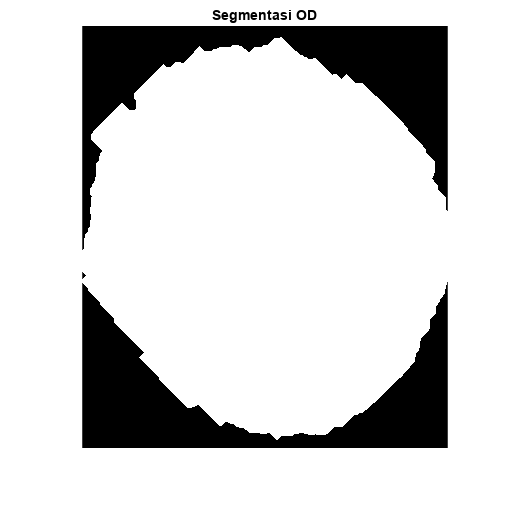

% Extract only the two largest blobs.
BW = binaryImage;
CC = bwconncomp(BW);
numPixels = cellfun(@numel,CC.PixelIdxList);
[biggest,idx] = max(numPixels);
BW(CC.PixelIdxList{idx}) = 0;
filteredForeground = BW;

% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
s = regionprops(dil,'basic');
centroids = cat(1,s.Centroid);
bbox = cat(1,s.BoundingBox);
x = s(1).Centroid(1,1) - 1/2*(bbox(3));
y = s(1).Centroid(1,2) - 1/2*(bbox(4));
figure, imshow(imcrop(openim, [x y bbox(3) bbox(4)]))
title('Segmentasi OD')

fprintf('Panjang (x) Segmentasi = %i Pixel\n', bbox(3))

Panjang (x) Segmentasi = 3.665000e+02 Pixel


fprintf('Panjang (y) Segmentasi = %i Pixel\n', bbox(4))

Panjang (y) Segmentasi = 4.245000e+02 Pixel


fprintf('Titik Pusat = (%i, %i) Pixel\n', s(1).Centroid(1,1), s(1).Centroid(1,2));

Titik Pusat = (4.824235e+02, 5.060079e+02) Pixel


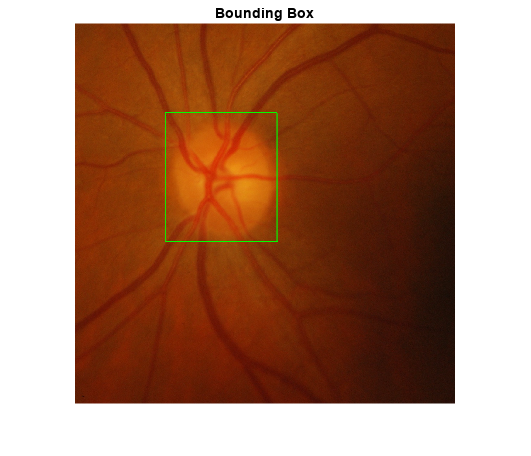


figure, imshow(I)
rectangle('Position',[x y bbox(3) bbox(4)],'EdgeColor','g')
title('Bounding Box')

%hold off
% Hitung Area, Luas BoundingBox, Titik tengah
fprintf('Area = %i Pixel\n', s(1).Area);

Area = 115168 Pixel


fprintf('Luas = %i Pixel^2\n', bbox(3)*bbox(4));

Luas = 1.555792e+05 Pixel^2


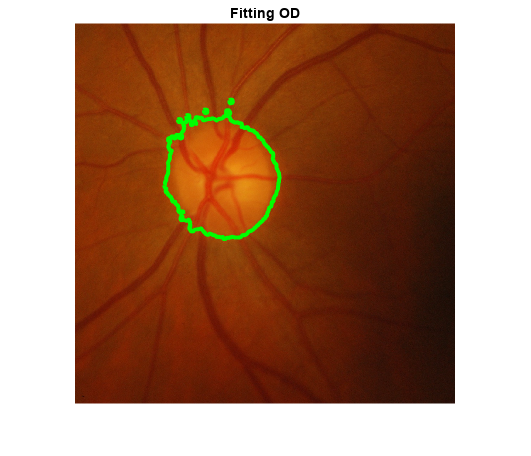


% figure, imshow(BW);
% % Fill holes in the blobs to make them solid.
%binaryImage = imfill(binaryImage, 'holes');
% % Display the binary image.
%dis(:,:,1)=immultiply(binaryImage,I(:,:,1));
%dis(:,:,2)=immultiply(binaryImage,I(:,:,2));
%dis(:,:,3)=immultiply(binaryImage,I(:,:,3));
%a = dil;
%stats = regionprops(double(a),'Centroid',...
%    'MajorAxisLength','MinorAxisLength')
%centers = stats.Centroid;
%diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
%radii = diameters/2;
% Plot the circles.
% figure,imshow(I)
%hold on
%viscircles(centers,radii);
%hold off

%% Overlay images
% Trace binary objects
[B, L] = bwboundaries(dil,'noholes');
figure
imshow(I)
hold on
for k = 1:length(B)
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), 'green', 'LineWidth', 3)
end
hold off
%viscircles(centers,radii);
title('Fitting OD')


s = regionprops(dil,{...
    'Centroid',...
    'MajorAxisLength',...
    'MinorAxisLength',...
    'Orientation'})

s = 5×1 struct array with fields:
    Centroid
    MajorAxisLength
    MinorAxisLength
    Orientation


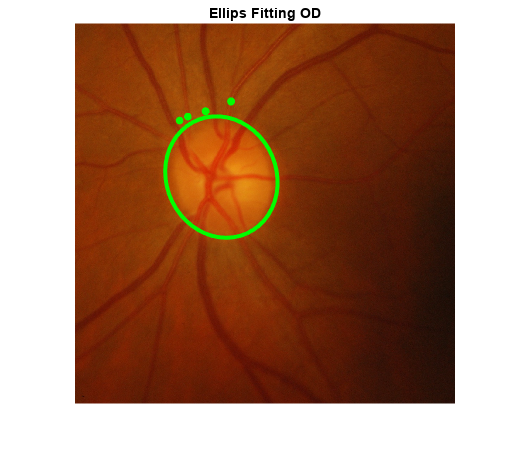


%figure
%imshow(bw,'InitialMagnification','fit')
figure
imshow(I)
t = linspace(0,2*pi,50);

hold on
for k = 1:length(s)
    a = s(k).MajorAxisLength/2;
    b = s(k).MinorAxisLength/2;
    Xc = s(k).Centroid(1);
    Yc = s(k).Centroid(2);
    phi = deg2rad(-s(k).Orientation);
    x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
    y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
    plot(x,y,'g','Linewidth',3)
end
title('Ellips Fitting OD')
hold off